% Parameter def
L = 3; % chord len
theta = deg2rad(0);
z = L / 3;
P1 = [0, 0];
P2 = [L * cos(theta), L * sin(theta)];
w1 = [cosd(35), sind(35)];% [1, 0.7];  % slope at P1
w2 = [cosd(-35), sind(-35)]; %[1, -0.7]; % slope at P2
s = 2; % blade spacing
A = 1.1; % blade throat area

sol = [w1.', -w2.']^-1 * (P2 - P1).';
v_mid = P1 + w1 * sol(1);

x1 = P1(1);
y1 = P1(2);
x2 = P2(1);
y2 = P2(2);
xmid = v_mid(1);
ymid = v_mid(2);

P = [x1, y1; xmid, ymid; xmid, ymid; x2, y2];

n = 100;

t = linspace(0, 1, n);

curve = zeros(n, 2);
normals = zeros(n, 2);
alt_normals = zeros(n, 2);

% calculate curve points for blade
for i = 1:n
    % https://pages.mtu.edu/~shene/COURSES/cs3621/NOTES/spline/Bezier/bezier-der.html
    B = (1 - t(i)).^3 * P(1,:) + 3 * (1 - t(i)).^2 * t(i) * P(2,:) + 3 * (1 - t(i)) * t(i).^2 * P(3,:) + t(i).^3 * P(4,:);
    curve(i, :) = B;

    dB = 3 * (1 - t(i)).^2 * (P(2,:) - P(1,:)) + 6 * (1 - t(i)) * t(i) * (P(3,:) - P(2,:)) + 3 * t(i).^2 * (P(4,:) - P(3,:));
    T = dB;
    N = [-T(2), T(1)];
    N = N / norm(N);
    N = A * N;
    normals(i, :) = curve(i, :) + N;
    alt_normals(i, :) = curve(i, :) - N;
end

% shift the curve up and down by blade spacing
curve_top = curve + [0, s];    % Shift upwards by s
curve_bottom = curve - [0, s]; % Shift downwards by s

figure(3)
hold on;
plot(P(:,1), P(:,2), 'ro--', 'LineWidth', 2);         % Control points for the main blade
plot([P1(1), P2(1)], [P1(2), P2(2)], 'go--', 'LineWidth', 2); % Chord
plot(curve(:,1), curve(:,2), 'b-', 'LineWidth', 2);    % Bézier curve for the main blade

% Plot the normal vectors
for i = 1:n
    plot([curve(i, 1), normals(i, 1)], [curve(i, 2), normals(i, 2)], 'r-');
    plot([curve(i, 1), alt_normals(i, 1)], [curve(i, 2), alt_normals(i, 2)], 'r-');
end

% Plot the top and bottom splines
plot(curve_top(:,1), curve_top(:,2), 'k-', 'LineWidth', 2);    % Bézier curve for the top blade
plot(curve_bottom(:,1), curve_bottom(:,2), 'k-', 'LineWidth', 2); % Bézier curve for the bottom blade

%---
x = [curve_bottom(1,1), alt_normals(1,1), alt_normals(end,1), curve_bottom(end,1)];
y = [curve_bottom(1,2), alt_normals(1,2), alt_normals(end,2), curve_bottom(end,2)];
xx = linspace(curve_bottom(1,1), curve_bottom(end,1), n)

xx =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5152    0.5455    0.5758    0.6061    0.6364    0.6667    0.6970    0.7273    0.7576    0.7879    0.8182    0.8485    0.8788    0.9091    0.9394    0.9697    1.0000    1.0303    1.0606    1.0909    1.1212    1.1515    1.1818    1.2121    1.2424    1.2727    1.3030    1.3333    1.3636    1.3939    1.4242    1.4545    1.4848


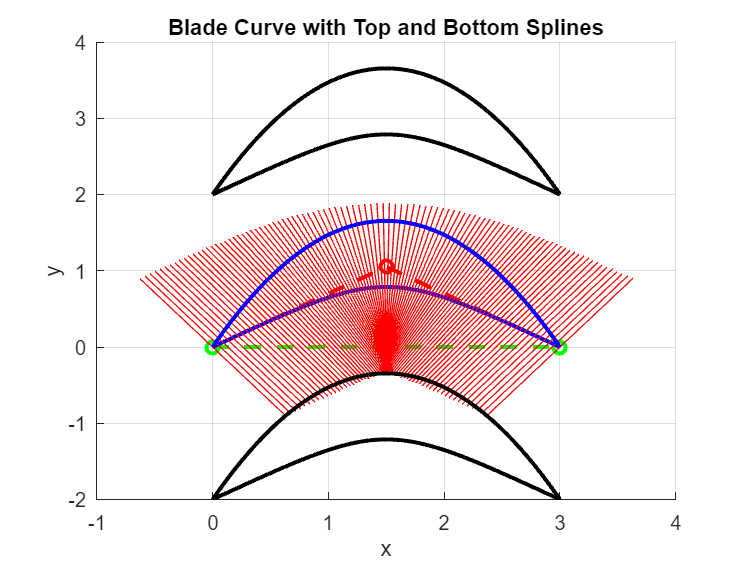

yy = spline(x,y,xx);

top_curve = [xx.', yy.'];
new_curve_middle = top_curve + [0, s];    % Shift upwards by s
new_curve_top = top_curve + 2 * [0, s]; % Shift upwards by 2s

% Plot the curves
plot(top_curve(:,1), top_curve(:,2), 'k-', 'LineWidth', 2);
plot(new_curve_middle(:,1), new_curve_middle(:,2), 'b-', 'LineWidth', 2);
plot(new_curve_top(:,1), new_curve_top(:,2), 'k-', 'LineWidth', 2);

% top_P = [curve_bottom(1,1), curve_bottom(1,2); alt_normals(1, 1), alt_normals(1, 2); alt_normals(n, 1), alt_normals(n, 2); curve_bottom(n,1), curve_bottom(n,2)];
% top_curve = zeros(n, 2);
% for i = 1:n
%     % https://pages.mtu.edu/~shene/COURSES/cs3621/NOTES/spline/Bezier/bezier-der.html
%     B = (1 - t(i)).^3 * top_P(1,:) + 3 * (1 - t(i)).^2 * t(i) * top_P(2,:) + 3 * (1 - t(i)) * t(i).^2 * top_P(3,:) + t(i).^3 * top_P(4,:);
%     top_curve(i, :) = B;
% end
% 
% % shift the curve up and down by blade spacing
% new_curve_middle = top_curve + [0, s];    % Shift upwards by s
% new_curve_top = top_curve + 2 * [0, s]; % Shift upwards by 2s
% 
% plot(top_curve(:,1), top_curve(:,2), 'k-', 'LineWidth', 2);
% plot(new_curve_middle(:,1), new_curve_middle(:,2), 'b-', 'LineWidth', 2);
% plot(new_curve_top(:,1), new_curve_top(:,2), 'k-', 'LineWidth', 2);


hold off;
grid on;
title('Blade Curve with Top and Bottom Splines');
xlabel('x');
ylabel('y');